# FFT Examples - Change the length of the FFT

Plot the frequency representation of the signal $x[n]$ by using the FFT function.

**Parameters** 

- 
$$x[n] = cos(2 \pi F_{0} nT_s) + cos(2 \pi F_1 n T_s)$$


- F_0 = 1 [kHz]

- F_1 = 5.123 [kHz]

- F_s = 16 [kHz];

- N=[8, 16, 32, 256]

**FFT Function (reference: "*****help fft")***

Y = fft(X,n) returns the n-point DFT. If no value is specified, Y is the same size as X.

- If X is a vector and the length of X is less than n, then X is padded with trailing zeros to length n.

- If X is a vector and the length of X is greater than n, then X is truncated to length n.

- If X is a matrix, then each column is treated as in the vector case.

- If X is a multidimensional array, then the first array dimension whose size does not equal 1 is treated as in the vector case.

## Clear

clc;            % Clear the text from the Command Window
clear;          % Remove all variables from the current workspace
close all;      % Close all figures

## Parameters

F_0 = 1e3;
F_1 = 5.123e3;
Fs = 16e3;
N=[8, 16, 32, 256];

## Exercise

Ts = 1/Fs;
len = 150;
n = 0:len-1;
x = cos(2*pi*F_0*Ts*n) + cos(2*pi*F_1*Ts*n);

% FFT
y1 = fft(x, N(1));
y2 = fft(x, N(2));
y3 = fft(x, N(3));
y4 = fft(x, N(4));

% Abs of y
y1 = abs(y1);
y2 = abs(y2);
y3 = abs(y3);
y4 = abs(y4);


## Plot

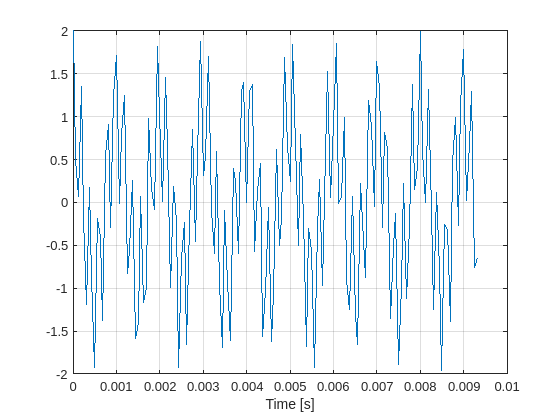

figure
plot(n*Ts, x)
grid on
xlabel('Time [s]')

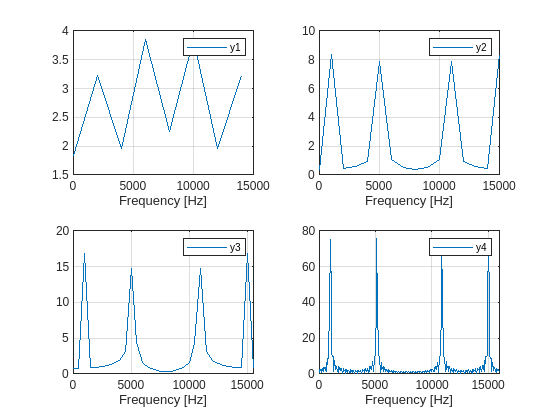


f_ax1 = (0:length(y1)-1)./length(y1)*Fs;
f_ax2 = (0:length(y2)-1)./length(y2)*Fs;
f_ax3 = (0:length(y3)-1)./length(y3)*Fs;
f_ax4 = (0:length(y4)-1)./length(y4)*Fs;

figure
subplot(2,2,1)
    plot(f_ax1, y1)
    grid on
    legend('y1')
    xlabel('Frequency [Hz]')
subplot(2,2,2)
    plot(f_ax2, y2)
    grid on
    legend('y2')
    xlabel('Frequency [Hz]')
subplot(2,2,3)
    plot(f_ax3, y3)
    grid on
    legend('y3')
    xlabel('Frequency [Hz]')
subplot(2,2,4)
    plot(f_ax4, y4)
    grid on
    legend('y4')
    xlabel('Frequency [Hz]')